## Calidad de imagenes por serie de tiempo por pixel de la cuenca del Río Pánuco

### del año 2000 al 2022

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok



calidad = 89;
anios = 2000:2022;

Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

### 2.- Filtrado de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla

tmp = info_hdf.anio >= 2000 & info_hdf.anio <=2023;

info_consulta = info_hdf(tmp,:);

[filas,~] = size(info_consulta);
disp("Total de imágenes: "+filas);

Total de imágenes: 521


### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo mapa MSE
mapa_rmse = zeros( ndvi_tam(1),ndvi_tam(2));
% arreglo mapa MAE
mapa_mae = zeros( ndvi_tam(1),ndvi_tam(2));
% arreglo mapa correlacion 
mapa_corr = zeros( ndvi_tam(1),ndvi_tam(2));
% mapa huecos
mapa_huecos = zeros( ndvi_tam(1),ndvi_tam(2));
% arreglo mapa de porcentaje de pixeles de mala calidad
mapa_pje_huecos = zeros( ndvi_tam(1),ndvi_tam(2));

% mapa nan en interpolacion
mapa_nan = zeros( ndvi_tam(1),ndvi_tam(2));

Recuperar toda la información y marcar los dias como baja calidad

bp=waitbar(0,'Obteniendo información'); 
for i=1:filas
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
    
    %barra de progreso
    waitbar(i/filas,bp);
end
close(bp); 

### 4.- Usar los datos obtenidos 

Mostrar mapa del promedio por pixel del periodo de estudio 

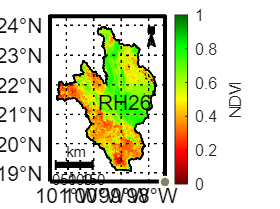

prom_arr_ndvi = m_mean_3dpp(arr_ndvi);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,prom_arr_ndvi,"",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");


%exportgraphics(gca,"img/promedio.png",'Resolution',300) 

Mostrar mapa del promedio de disponibilidad por pixel del periodo de estudio 

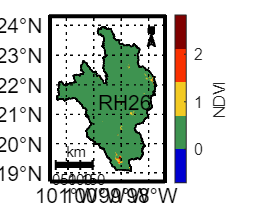

prom_arr_ndvi_qa = m_mean_3dpp(arr_ndvi_qa);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,prom_arr_ndvi_qa,"",[],m_colmap('jet',5),"NDVI");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");


%exportgraphics(gca,"img/promedio.png",'Resolution',300) 

### 5.- Hacer el análisis por pixel 

D = arr_ndvi;
Q = arr_ndvi_qa;

tam_arr = size(D);
D = permute(D,[1 3 2]);
Q = permute(Q,[1 3 2]);

ma0 = zeros( tam_arr(1),tam_arr(2));
ma1 = zeros(tam_arr(1),tam_arr(2));

tmp_x = 1:tam_arr(3);

bp=waitbar(0,'Procesando'); 

 for i=1:tam_arr(1)
     for j=1:tam_arr(2)
         [mapa_rmse(i,j),mapa_mae(i,j),mapa_corr(i,j),mapa_huecos(i,j),mapa_pje_huecos(i,j),data_n] = m_analisis_qa(D(i,:,j),Q(i,:,j));

         if( sum (isnan(data_n)) >0 )
             mapa_nan(i,j)=1;
         end
     end
     waitbar(i/tam_arr(1),bp);

 end
 close (bp);


% i=364;
% j=74;
% 
% [t1,t2,t3,t4,t5,t6] = m_analisis_qa(D(i,:,j),Q(i,:,j));
% 
i=331;
j=292;

[t1,t2,t3,t4,t5,t6] = m_analisis_qa(D(i,:,j),Q(i,:,j));
tmp = D(i,:,j);
tval_rmse = rmse(tmp,t6);


### 6.- Mostrar los resultados

Mostrar mapa de el procentaje de pixeles de mala calidad 

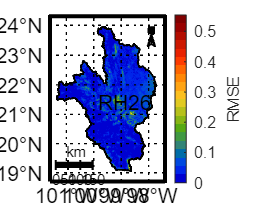

figure;
mapa_rmse(area_estudio==false)=nan;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_rmse,"",[],m_colmap('jet',20),"RMSE");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

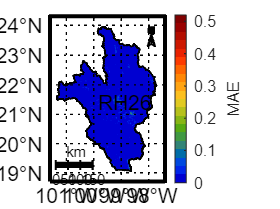


figure;
mapa_mae(area_estudio==false)=nan;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_mae,"",[],m_colmap('jet',20),"MAE");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

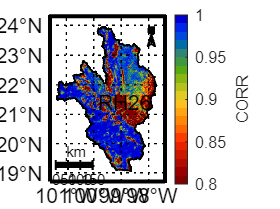


figure;
mapa_corr(area_estudio==false)=nan;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_corr,"",[.8 1],flipud(m_colmap('jet',20)),"CORR");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

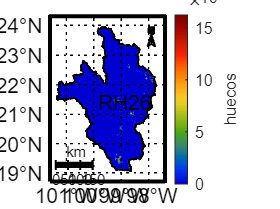


figure;
mapa_huecos(area_estudio==false)=nan;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_huecos,"",[],m_colmap('jet',100),"huecos");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

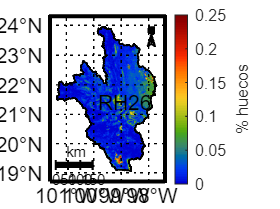


figure;
mapa_pje_huecos(area_estudio==false)=nan;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_pje_huecos,"",[0 .25],m_colmap('jet',100),"% huecos");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

### 7.- Mostrar la información en graficas de lineas

%RMSE
serie = rmmissing( reshape(mapa_rmse,[],1))

serie =    0.022632025637423
   0.031403024661331
   0.041418129564245
   0.025823620901411
   0.031150680395493
   0.021091140942923
   0.042474821164169
   0.010448366914877
   0.023965471202979
                   0


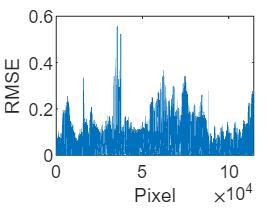

tam_serie = length(serie);
figure;
plot(serie);
xlabel('Pixel');
%xticks(1:4);
%xticklabels(lbl_estaciones);
ylabel('RMSE');

%xlim([1 4]);
%ylim([0 0.6]);

serie(serie>0.05)=nan;
disp("% rm 20% "+ length(find(isnan(serie)))/tam_serie*100 +"%" );

% rm 20% 26.6323%


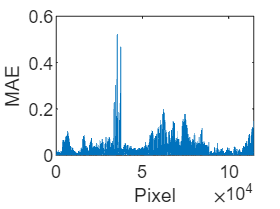


%MAE
figure;
plot(rmmissing( reshape(mapa_mae,[],1)));
xlabel('Pixel');
%xticks(1:4);
%xticklabels(lbl_estaciones);
ylabel('MAE');

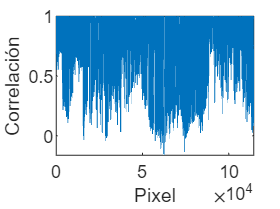

%xlim([1 4]);
%ylim([0 0.6]);

%MAE
figure;
plot(rmmissing( reshape(mapa_corr,[],1)));
xlabel('Pixel');
%xticks(1:4);
%xticklabels(lbl_estaciones);
ylabel('Correlación');

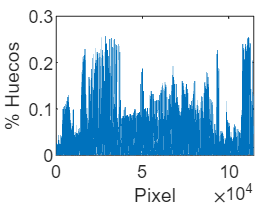

%xlim([1 4]);
%ylim([0 0.6]);


%MAE
figure;
plot(rmmissing( reshape(mapa_pje_huecos,[],1)));
xlabel('Pixel');
%xticks(1:4);
%xticklabels(lbl_estaciones);
ylabel('% Huecos');

%xlim([1 4]);
%ylim([0 0.6]);